n_points = 201;
lo_bound = -3;
hi_bound = 3;

dx = (hi_bound - lo_bound) / (n_points - 1);

t = linspace(lo_bound, hi_bound, n_points)

t =    -3.0000   -2.9700   -2.9400   -2.9100   -2.8800   -2.8500   -2.8200   -2.7900   -2.7600   -2.7300   -2.7000   -2.6700   -2.6400   -2.6100   -2.5800   -2.5500   -2.5200   -2.4900   -2.4600   -2.4300   -2.4000   -2.3700   -2.3400   -2.3100   -2.2800   -2.2500   -2.2200   -2.1900   -2.1600   -2.1300   -2.1000   -2.0700   -2.0400   -2.0100   -1.9800   -1.9500   -1.9200   -1.8900   -1.8600   -1.8300   -1.8000   -1.7700   -1.7400   -1.7100   -1.6800   -1.6500   -1.6200   -1.5900   -1.5600   -1.5300


x = [3, 2]';

v0 = [-2 -4]'; % offset
v = [-2 5]'; % slope

A = v .* t + v0

A =     4.0000    3.9400    3.8800    3.8200    3.7600    3.7000    3.6400    3.5800    3.5200    3.4600    3.4000    3.3400    3.2800    3.2200    3.1600    3.1000    3.0400    2.9800    2.9200    2.8600    2.8000    2.7400    2.6800    2.6200    2.5600    2.5000    2.4400    2.3800    2.3200    2.2600    2.2000    2.1400    2.0800    2.0200    1.9600    1.9000    1.8400    1.7800    1.7200    1.6600    1.6000    1.5400    1.4800    1.4200    1.3600    1.3000    1.2400    1.1800    1.1200    1.0600
  -19.0000  -18.8500  -18.7000  -18.5500  -18.4000  -18.2500  -18.1000  -17.9500  -17.8000  -17.6500  -17.5000  -17.3500  -17.2000  -17.0500  -16.9000  -16.7500  -16.6000  -16.4500  -16.3000  -16.1500  -16.0000  -15.8500  -15.7000  -15.5500  -15.4000  -15.2500  -15.1000  -14.9500  -14.8000  -14.6500  -14.5000  -14.3500  -14.2000  -14.0500  -13.9000  -13.7500  -13.6000  -13.4500  -13.3000  -13.1500  -13.0000  -12.8500  -12.7000  -12.5500  -12.4000  -12.2500  -12.1000  -11.9500  -11.8000  -11

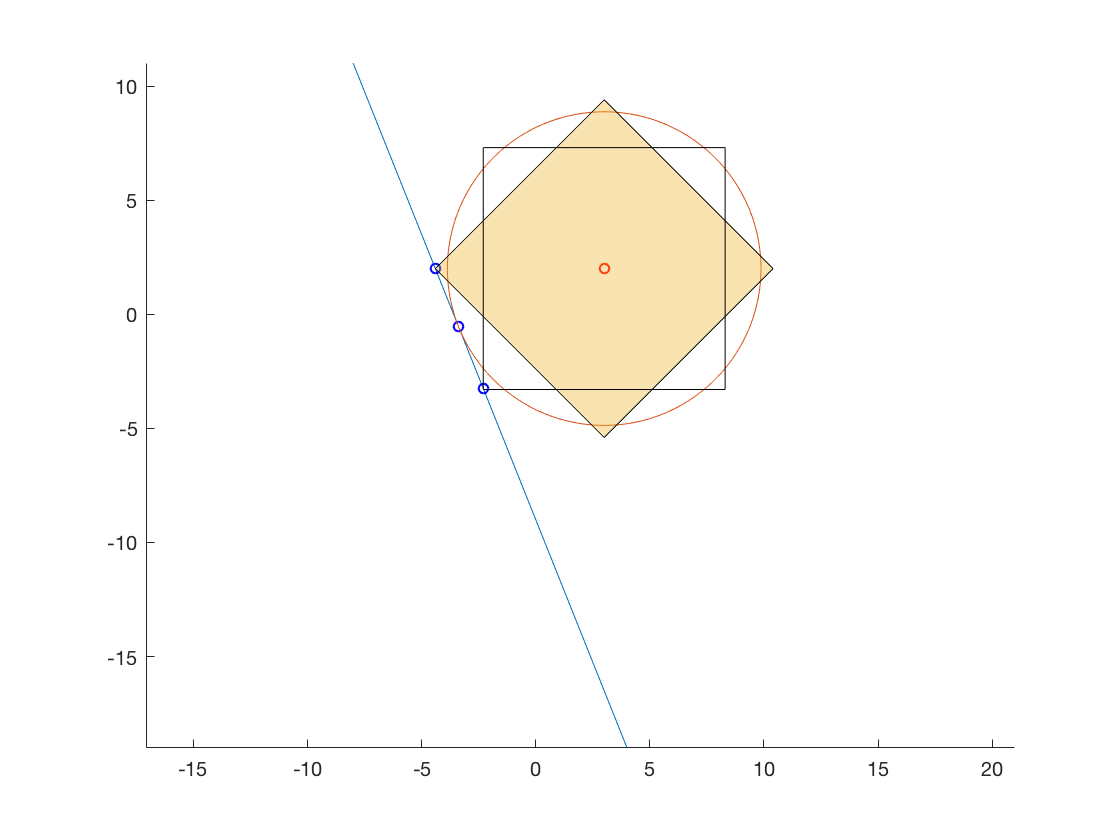

figure; hold on
axis equal

plot(x(1, :), x(2, :), 'ro', 'MarkerSize', 5);
plot(A(1, :), A(2, :));

% l2-norms
l2_norm = sqrt(dot(A - x, A - x));
[~, pos] = min(l2_norm);

plot(A(1, pos), A(2, pos), 'bo', 'MarkerSize', 5);
circle(x(1, :), x(2, :), l2_norm(pos))

% L1-norm  
l1_norm = sum(abs(A - x), 1);
[~, pos] = min(l1_norm);

plot(A(1, pos), A(2, pos), 'bo', 'MarkerSize', 5);
diamond(x(1, :), x(2, :), l1_norm(pos))

% L-inf norm
l_inf_norm = max(abs(A - x));
[min_dist, pos] = min(l_inf_norm);
plot(A(1, pos), A(2, pos), 'bo', 'MarkerSize', 5);
square(x(1, :), x(2, :), l_inf_norm(pos))

function circle(x, y, r)
% x and y are the coordinates of the center of the circle
% r is the radius of the circle
% 0.01 is the angle step, bigger values will draw the circle faster but
% you might notice imperfections (not very smooth)
    theta = 0:0.01:2 * pi; 
    xp = r * cos(theta);
    yp = r * sin(theta);
    plot(x + xp, y + yp);
end

function diamond(x, y, r)
% by diamond I mean a rhombus of equal sides, which is essentially
% the shape of L1 norm ball.
% x, y - centre of the diamond
% r - distance between the centre to any of the vertices
    vertices = [x-r y; x y-r; x+r y; x y+r];
    poly = polyshape(vertices);
    plot(poly);
end

function square(x, y, r)
% x, y - centre of the square
% r - distance from centre to any side. Equal to half of the side length
    side_length = 2 * r;
    rectangle('Position', ...
        [x - side_length/2, y - side_length/2, side_length, side_length]);
end